DataStruct = load('data.mat');
Data = DataStruct.data;
labels = DataStruct.class;

From histograms for each features we can observe differences in scales of three features. For feature 1, the scale is 10^(-5) we can determine the measurement as Bytes. For feature 2, the scale is 10^(7) we can determine the measurment as Terabytes. For feature 3, the scale is 10^(0) we can determine the measurement as Megabytes. Difference in measurements can have different impacts on parametric and non-parametric classification techniques. Parametric classification techniques will be affected in aspects of data distributions where data are located differently with different measurments and resulting in misclassifications. Non-parametric classification techniques will be affected in terms of weights, as larger values have higher weights in error functions. 

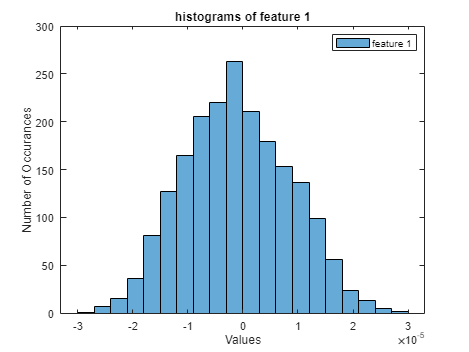

feature1 = Data(:,1);
feature2 = Data(:,2);
feature3 = Data(:,3);

% histogram of feature 1
histogram(feature1);
legend("feature 1");
title('histograms of feature 1');
xlabel('Values');
ylabel('Number of Occurances');

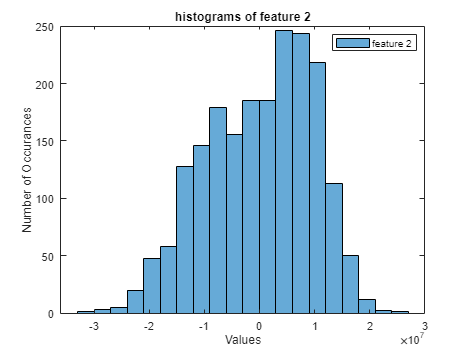


% histogram of feature 2
histogram(feature2);
legend("feature 2");
title('histograms of feature 2');
xlabel('Values');
ylabel('Number of Occurances');

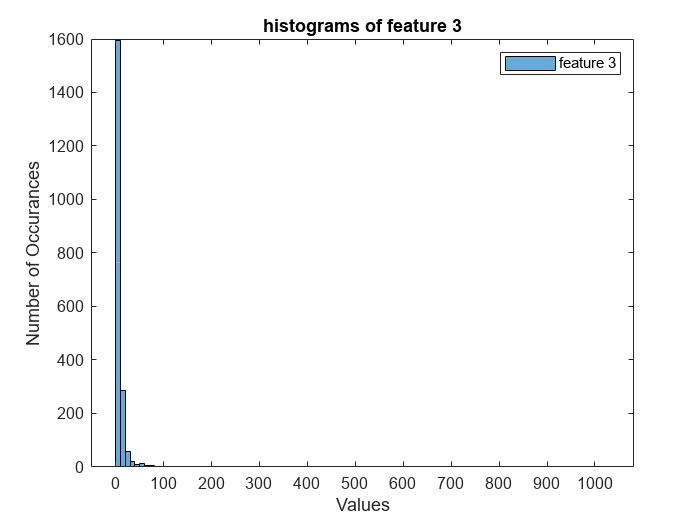


% histogram of feature 3
histogram(feature3);
legend("feature 3");
title('histograms of feature 3');
xlabel('Values'); 
ylabel('Number of Occurances'); 

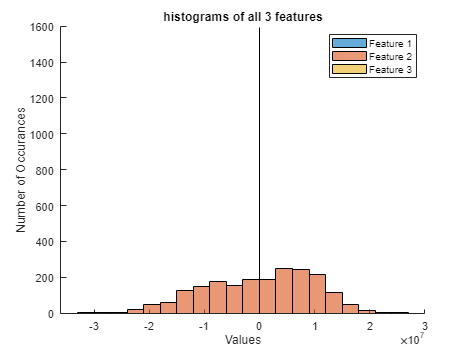


% histogram overall
plot_hist(feature1, feature2, feature3, 'histograms of all 3 features');

As we can observe from new histograms, the scale is now from -1 to 1 and the distributions of 3 features remain the same individually (together the distribution of the dataset changed significantly). To scale data to a range [-1 1], we use formula 2 * ((xi – xmin) / (xmax – xmin)) – 1. The key difference between range [-1, 1] and [0, 1] is that range [0, 1] could result in lossing information, becuase 0 means no weights and in our case feautre 3 will have dominating number of 0s.

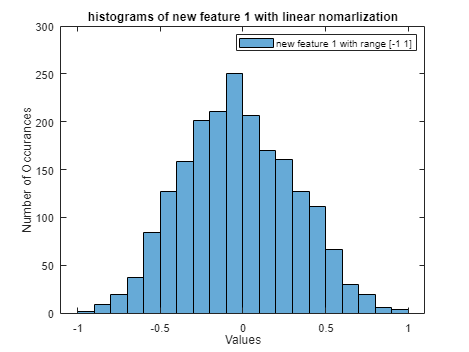

new_feature1 = MinMaxNorm(feature1);
new_feature2 = MinMaxNorm(feature2);
new_feature3 = MinMaxNorm(feature3);

data_norm = [new_feature1 new_feature2 new_feature3];

% histogram of new feature 1
histogram(new_feature1);
legend("new feature 1 with range [-1 1]");
title('histograms of new feature 1 with linear nomarlization');
xlabel('Values');
ylabel('Number of Occurances');

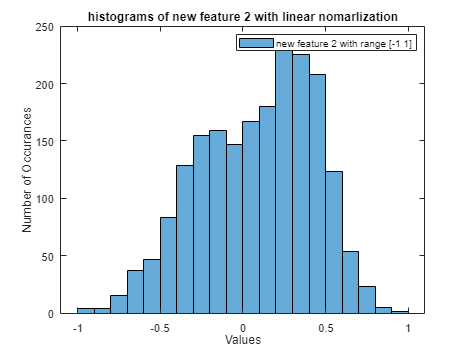


% histogram of new feature 2
histogram(new_feature2);
legend("new feature 2 with range [-1 1]");
title('histograms of new feature 2 with linear nomarlization');
xlabel('Values');
ylabel('Number of Occurances');

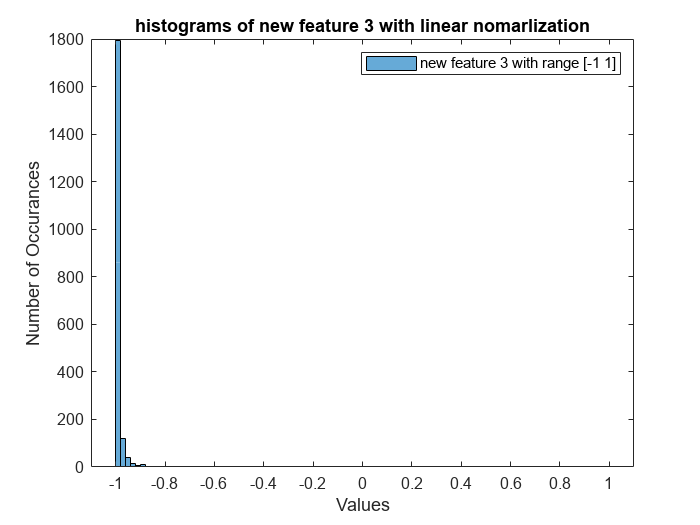


% histogram of new feature 3
histogram(new_feature3);
legend("new feature 3 with range [-1 1]");
title('histograms of new feature 3 with linear nomarlization');
xlabel('Values'); 
ylabel('Number of Occurances');

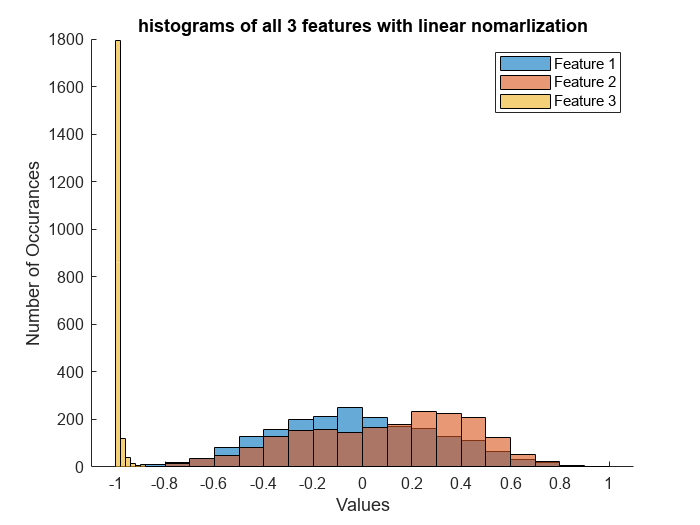


% histogram overall
plot_hist(new_feature1, new_feature2, new_feature3, 'histograms of all 3 features with linear nomarlization');

[train_set, test_set, train_labels, test_labels] = train_test_split(0.25, data_norm, labels);
disp(size(train_set));

   500     3




% Bayes classifier
% find index of ones and zeros for both train and test
class1_trainIdx = find(train_labels==1);
class2_trainIdx = find(train_labels==2);
class1_testIdx = find(test_labels==1);
class2_testIdx = find(test_labels==2);

% separate class1 and class2 test set
True_class1 = find(test_labels==1);
True_class2 = find(test_labels==2);

% find data for class 1 and class 2 in train\test dataset
class1_train = train_set(class1_trainIdx,:);
class2_train = train_set(class2_trainIdx,:);
class1_test = test_set(class1_testIdx,:);
class2_test = test_set(class2_testIdx,:);

% calculate probability of each class
num_class1 = sum(train_labels(:) == 1);
num_class2 = sum(train_labels(:) == 2);
num_train = length(train_set);
prob_class1 = num_class1/num_train;
prob_class2 = num_class2/num_train;

% calculate mean and covariance of each class
class1_mu = mean(class1_train);
class2_mu = mean(class2_train);
class1_cov = cov(class1_train);
class2_cov = cov(class2_train);

% create discriminant function
g1 = Discriminant(test_set, class1_mu', class1_cov, prob_class1);
g2 = Discriminant(test_set, class2_mu', class2_cov, prob_class2);

% predict and then compare with true test labels
Pred_class1 = find(g1>g2);
Pred_class2 = find(g2>g1);

% compare predictions and true labels
diff1_idx = ismember(Pred_class1,True_class1);
diff2_idx = ismember(Pred_class2,True_class2);

% calculate accuracy 
acc = (length(find(diff1_idx))+length(find(diff2_idx)))/1500;

% construct confusion matrix
TP = length(find(diff1_idx));
TN = length(find(diff2_idx));
FP = length(find(~diff1_idx));
FN = length(find(~diff2_idx));
Confusion = [TP FN;FP TN];

disp('Bayes Confusion matrix: ')

Bayes Confusion matrix: 


disp(Confusion)

   714    31
    14   741



disp('Bayes error rate: ')

Bayes error rate: 


disp(100-acc*100)

     3




net = patternnet();
net.inputs{1}.processFcns;
net.trainParam.showWindow = false;
[net,tr] = train(net,train_set' ,onehotencode(categorical(train_labels),1));

pred_net = net(test_set.');
pred_net = vec2ind(pred_net);
% get performance
perf = perform(net,test_labels,pred_net);
disp('Nerual Nets performance');

Nerual Nets performance


disp(perf);

   2.2204e-16




% calculate accuracy
net_diff1_idx = ismember(find(pred_net==1),class1_testIdx);
net_diff2_idx = ismember(find(pred_net==2),class2_testIdx);
net_acc = (sum(net_diff1_idx)+sum(net_diff2_idx))/length(test_set);
diff = sum(abs(round(pred_net)-test_labels));
acc = (1500-diff)/1500;

disp('NN error rate: ');

NN error rate: 


disp(100-acc*100);

    2.8667



Both classifiers have good performance; however, as we can observe from predictions plotted in histograms on both classifiers, feature 3 is dominating the classification processes.The vast majority of number of occurances resides near -1 for both classifiers, which is feature 3 according to legends. 

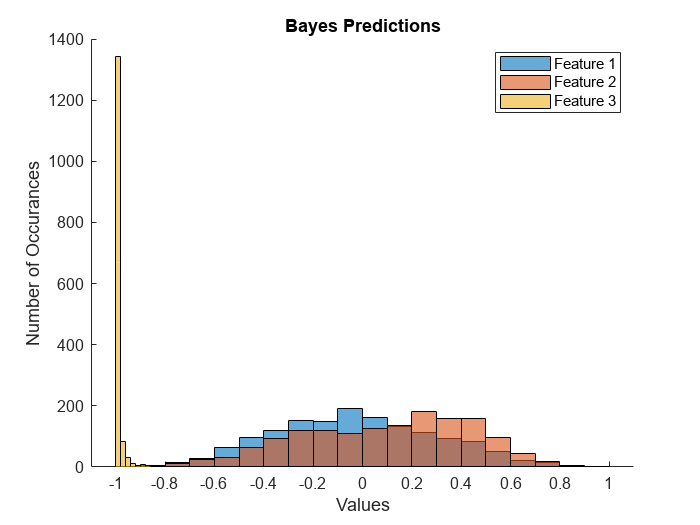

% get Bayes class 1 and class 2 predictions
Bayes_class1 = test_set(Pred_class1,:);
Bayes_class2 = test_set(Pred_class2,:);
Bayes_pred = [Bayes_class1; Bayes_class2];

% get Bayes class 1 and class 2 predictions
Net_class1 = test_set(find(pred_net==1),:);
Net_class2 = test_set(find(pred_net==2),:);
Net_pred = [Net_class1; Net_class2];

% plot all features of predictions from both classifiers histograms
plot_hist(Bayes_pred(:,1),Bayes_pred(:,2),Bayes_pred(:,3),'Bayes Predictions');

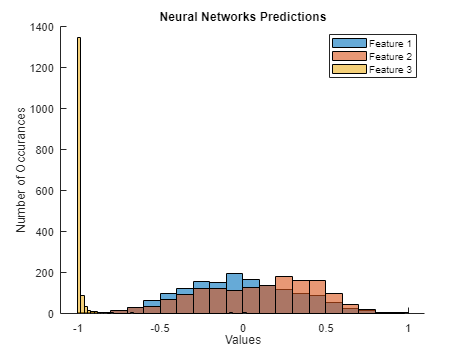

plot_hist(Net_pred(:,1),Net_pred(:,2),Net_pred(:,3),'Neural Networks Predictions');

Firstly, linear normalizations only restricts data in a given range, but they could twist the distribution of datasets and they are sensative to outliers. From the previous histogram plots of the datatset, we can observe that although the distribution of each feature does not change by plotting them individually, but the distribution of the dataset as a whole changed. The twisted distribution and outliers could result in misinfomation and information loss. Secondly, there are many different distributions that are non-linear, such as exponential and pareto, so linear normalization is simple but a naive apporach.

A more appropriate approach would be piecewise normalizations. We first plot whole dataset and each feature individually to observe distributions. Then, we apply different normalizations on each feature according to different distributions and behaviours of the feature. For example, for feature 3 in this case,instead of using min-max normalization we could use exponential (log) normalization for skewed data. On the hand, if there are outliers that are unussually far way from the distribution we could use robust scaler which is less sensative to outliers by using median.

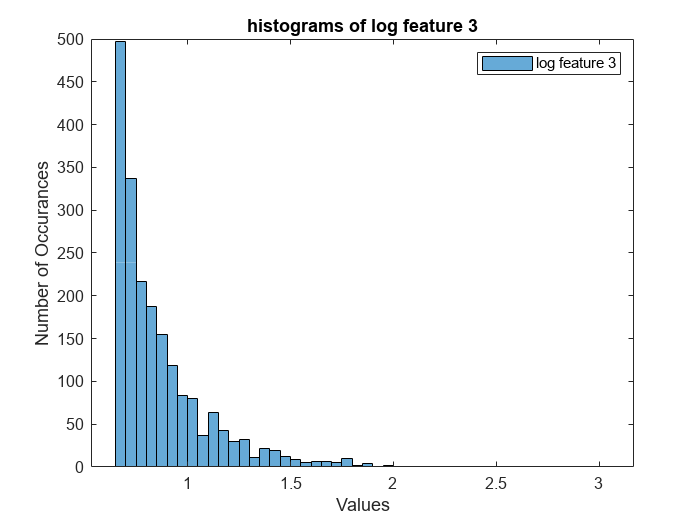

% apply log normalization on feature 3
% everyting else unchange
log_feature3 = log10(feature3);

% histogram of feature 3
histogram(log_feature3);
legend("log feature 3");
title('histograms of log feature 3');
xlabel('Values'); 
ylabel('Number of Occurances');

% new dataset
log_data = [new_feature1 new_feature2 log_feature3];

% traint test split
[log_train_set, log_test_set, log_train_labels, log_test_labels] = train_test_split(0.25, log_data, labels);
disp(size(log_train_set));

   500     3




% Train Bayes classifier
% find index of ones and zeros for both train and test
log_class1_trainIdx = find(log_train_labels==1);
log_class2_trainIdx = find(log_train_labels==2);
log_class1_testIdx = find(log_test_labels==1);
log_class2_testIdx = find(log_test_labels==2);

% separate class1 and class2 test set
log_True_class1 = find(log_test_labels==1);
log_True_class2 = find(log_test_labels==2);

% find data for class 1 and class 2 in train\test dataset
log_class1_train = log_train_set(log_class1_trainIdx,:);
log_class2_train = log_train_set(log_class2_trainIdx,:);
log_class1_test = log_test_set(log_class1_testIdx,:);
log_class2_test = log_test_set(log_class2_testIdx,:);

% calculate probability of each class
log_num_class1 = sum(log_train_labels(:) == 1);
log_num_class2 = sum(log_train_labels(:) == 2);
log_num_train = length(log_train_set);
log_prob_class1 = log_num_class1/log_num_train;
log_prob_class2 = log_num_class2/log_num_train;

% calculate mean and covariance of each class
log_class1_mu = mean(log_class1_train);
log_class2_mu = mean(log_class2_train);
log_class1_cov = cov(log_class1_train);
log_class2_cov = cov(log_class2_train);

log_net = patternnet();
log_net.inputs{1}.processFcns;
log_net.trainParam.showWindow = false;
[log_net,log_tr] = train(log_net,log_train_set' ,onehotencode(categorical(log_train_labels),1));

We can observe that percentage errors of both classifiers slightly drop

% create discriminant function
log_g1 = Discriminant(log_test_set, log_class1_mu', log_class1_cov, log_prob_class1);
log_g2 = Discriminant(log_test_set, log_class2_mu', log_class2_cov, log_prob_class2);

% predict and then compare with true test labels
log_Pred_class1 = find(log_g1>log_g2);
log_Pred_class2 = find(log_g2>log_g1);

% compare predictions and true labels
log_diff1_idx = ismember(log_Pred_class1,log_True_class1);
log_diff2_idx = ismember(log_Pred_class2,log_True_class2);

% calculate accuracy 
log_acc = (length(find(log_diff1_idx))+length(find(log_diff2_idx)))/1500;

% construct confusion matrix
log_TP = length(find(diff1_idx));
log_TN = length(find(diff2_idx));
log_FP = length(find(~diff1_idx));
log_FN = length(find(~diff2_idx));
log_Confusion = [log_TP log_FN;log_FP log_TN];

disp('Bayes Confusion matrix with log normalization: ');

Bayes Confusion matrix with log normalization: 


disp(log_Confusion);

   714    31
    14   741



disp('Bayes error rate: ');

Bayes error rate: 


disp(100-log_acc*100);

    2.0667




% Neura Nets Predictions
log_pred_net = log_net(log_test_set.');
log_pred_net = vec2ind(log_pred_net);
% get performance
log_perf = perform(log_net,log_test_labels,log_pred_net);
disp('Nerual Nets performance');

Nerual Nets performance


disp(perf);

   2.2204e-16




% calculate accuracy
log_net_diff1_idx = ismember(find(log_pred_net==1),log_class1_testIdx);
log_net_diff2_idx = ismember(find(log_pred_net==2),log_class2_testIdx);
log_net_acc = (sum(log_net_diff1_idx)+sum(log_net_diff2_idx))/length(log_test_set);
log_diff = sum(abs(round(log_pred_net)-log_test_labels));
log_acc = (1500-log_diff)/1500;

disp('NN error rate: ');

NN error rate: 


disp(100-log_acc*100);

    2.5333



functions 

% function for discriminant analysis

function gi = Discriminant(x, mu, sigma, prob)
    % caluclate terms for discriminat function separatly
    inv_sigma = inv(sigma);
    cap_w = -1/2*inv_sigma;
    w = inv_sigma*mu;
    w_const = -1/2*(mu.')*inv_sigma*mu - 1/2*log(det(sigma)) + log(prob);
    
    % create discriminant function
    gi = dot((x*cap_w).',x.') + (w.')*x.' + w_const;
end

% scale range to [-1 1]
function scaled = MinMaxNorm(data)
    scaled = 2.*(data - min(data))./(max(data) - min(data))-1;
end

% train test split
function [train, test, train_y, test_y]=train_test_split(ratio, dataset, y)
    s = size(dataset);
    m = s(1);
    rand_idx = randperm(m);
    train_idx = rand_idx(1:round(ratio*m));
    test_idx = rand_idx(round(ratio*m)+1:end);
    train = dataset(train_idx,:);
    test = dataset(test_idx,:);
    train_y = y(train_idx);
    test_y = y(test_idx);
end

function plot_hist(F1, F2, F3, str)
    figure
    hold on
    histogram(F1);
    histogram(F2);
    histogram(F3);
    legend("Feature 1","Feature 2", "Feature 3");
    title(str);
    xlabel('Values'); 
    ylabel('Number of Occurances');
    hold off
end